Import data

data = readmatrix('data.csv');
x = data(:,3:32);
y = data(:,2);
m = length(y);

Visualization of the data

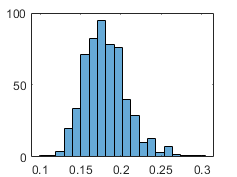

histogram(x(:,9),20);

%plot(x(:,3),y,'o');

Normalize the data betweem 0 -> 1

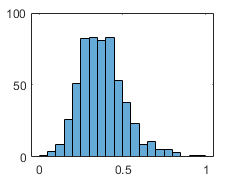

y2 = log(1+y);
for i=3:30
    x2(:,i) = (x(:,i)-min(x(:,i)))/(max(x(:,i))-min(x(:,i)));
end
histogram(x2(:,9),20);

Train the ANN 

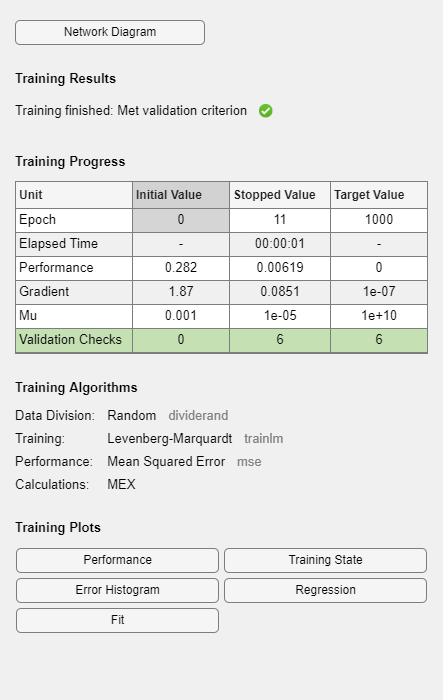

x_transp = x2';
y_transp = y';
hiddenLayerSize = 10;
net = fitnet(hiddenLayerSize);
net.divideParam.trainRatio = 90/100;
net.divideParam.valRatio = 10/100;
net.divideParam.testRatio = 0/100;
[net, tr] = train(net, x_transp, y_transp);

Model performance

yTrain = net(x_transp(:,tr.trainInd));
yTrainTrue = y_transp(tr.trainInd);
trainRMSE = sqrt(mean((yTrain - yTrainTrue).^2));
yVal = net(x_transp(:,tr.valInd));
yValTrue = y_transp(tr.valInd);
valRMSE = sqrt(mean((yVal - yValTrue).^2));

Visualize the predictions of the model

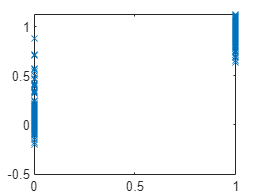

%plot(yTrainTrue, yTrain, 'x');

Optimize the number of neurons

%for i = 1:60
%   hiddenLayerSize = i;
%   net = fitnet(hiddenLayerSize);
%   net.divideParam.trainRatio = 90/100;
%   net.divideParam.valRatio = 10/100;
%   net.divideParam.testRatio = 0/100;
    
    %training the ANN
%   [net, tr] = train(net, x_transp, y_transp);

    %caclulate rmse
%   yTrain = net(x_transp(:,tr.trainInd));
%   yValTrue = y_transp(tr.valInd);
%   yTrainTrue = y_transp(tr.trainInd);
%   yVal = net(x_transp(:,tr.valInd));
    %train set RMSE
%   rmse_train(i) = sqrt(mean((yTrain - yTrainTrue).^2));
%   validation set RMSE
%   rmse_val(i) = sqrt(mean((yVal - yValTrue).^2));
%end

Select the optimal number of neurons for the ANN's hidden layer

%plot(1:60, rmse_train); hold on;
%plot(1:60, rmse_val); hold off;